# Problem Description

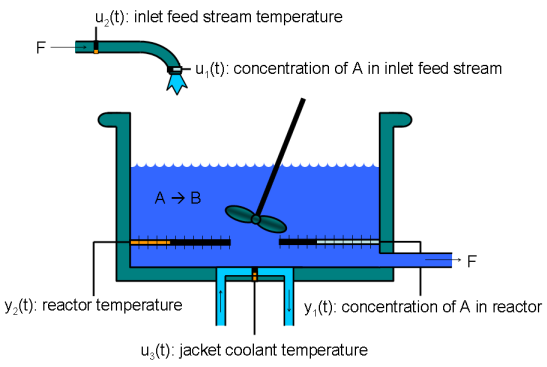

The CSTR system is modeled using basic accounting and energy  conservation principles. The change of the concentration of reagent A in the vessel per time unit d C_A(t)/dt (= d y_1(t)/dt) can be modeled as:

`  d C_A(t)`

`  -------- = F/V*(C_Af(t)-C_A(t)) - r(t)`

`     dt`

where the first term expresses concentration  changes due to differences between the concentration of reagent A in the inlet stream and in the vessel, and the second term expresses  concentration changes (reaction rate) that occurs due to the chemical  reaction in the vessel. The reaction rate per unit volume is described  by Arrhenius rate law:

`  r(t) = k_0*exp(-E/(R*T(t)))*C_A(t)`

which states that the rate of a chemical reaction increases exponentially  with the absolute temperature. k_0 is here an unknown nonthermal  constant, E is the activation energy, R Boltzmann's ideal gas constant  and T(t) (= y_2(t)) the temperature in the reactor.

Similarly,  using the energy balance principle (assuming constant volume in the  reactor), the temperature change per time unit d T(t)/dt in the reactor  can be modeled as:

`  d T(t)`

`  ------ = F/V(T_f(t)-T(t)) - (H/c_p*rho)*r(t) - (U*A)/(c_p*rho*V)*(T(t)-T_j(t))`

`    dt`

where the first and third terms describe changes  due to that the feed stream temperature T_f(t) and the jacket coolant  temperature T_j(t) differ from the reactor temperature, respectively.  The second term is the influence on the reactor temperature caused by  the chemical reaction in the vessel. In this equation, H is a heat of  reaction parameter, c_p a heat capacity term, rho a density term, U an  overall heat transfer coefficient and A the area for the heat exchange  (coolant/vessel area).

Put together, the CSTR has three input signals:

`  u_1(t) = C_Af(t)  Concentration of A in inlet feed stream [kgmol/m^3].`

`  u_2(t) = T_f(t)   Inlet feed stream temperature [K].`

`  u_3(t) = T_j(t)   Jacket coolant temperature [K].`

and two output signals:

`  y_1(t) = C_A(t)   Concentration of A in reactor tank [kgmol/m^3].`

`  y_2(t) = T(t)     Reactor temperature [K]`

## Import Casadi

clc, clear all
addpath('C:\dev\casadi-windows-matlabR2016a-v3.5.2');
%addpath('\\home.org.aalto.fi\sliczno1\data\Documents\casadi-windows-matlabR2016a-v3.5.1');
import casadi.*

## Parameters

p(1)   = 1;             % Volumetric flow rate (volume/time) [m^3/h]
p(2)   = 1;             % Volume in reactor [m^3]
p(3)   = 3.5e+07;       % Pre-exponential nonthermal factor [1/h]
p(4)   = 11850;         % Activation energy [kcal/kgmol]
p(5)   = 1.98589;       % Boltzmann's ideal gas constant [kcal/(kgmo..]
p(6)   = -5960;         % Heat of reaction [kcal/kgmol]
p(7)   = 480;           % Heat capacity times density [kcal/(m^3*K)]
p(8)   = 145;           % Overall heat transfer coefficient times tank area [kcal/(K*h)]

## Model and Integrator

f = @(x,u) cstr_m(0, x, u, p);
g = @(x)   modelOUT(0, x, p);

%% Build integrator

%Variables
Nx = 2;
Nu = 3;
Ny = 1;

% Time variables
simulationTime       = 1/4;                                         % Minutes 
timeStep             = 1/200;                                       % Minutes      

timeStep_in_seconds  = timeStep * 60;                               % Seconds
simulationTime_in_seconds = simulationTime * 60;                    % Seconds
nSteps    = ceil(simulationTime_in_seconds / timeStep_in_seconds);  % 

% Integrator
F = buildIntegrator(f, [Nx,Nu] , timeStep_in_seconds);

## Simulation without control

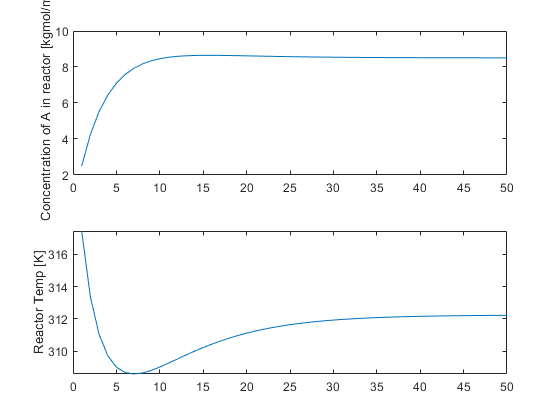


InitialStates = [0 325];                 % Initial value of the initial states.

feedConc    = 10  * ones(1,nSteps);   % kgmol/m^3
feedTemp    = 298 * ones(1,nSteps);   % Kelvin
jacketTemp  = 298 * ones(1,nSteps);   % Kelvin

u = [feedConc', feedTemp', jacketTemp'];

x0 = [InitialStates(1)*ones(1,1);
      InitialStates(2)*ones(1,1)];

[yout,~,xout] = simulateSystem(F, g, x0, u);

subplot(2,1,1)
plot(yout(1,:)')
ylabel('Concentration of A in reactor [kgmol/m^3]')
subplot(2,1,2)
plot(xout(2,:)')
ylabel('Reactor Temp [K]')

## Simulation with control

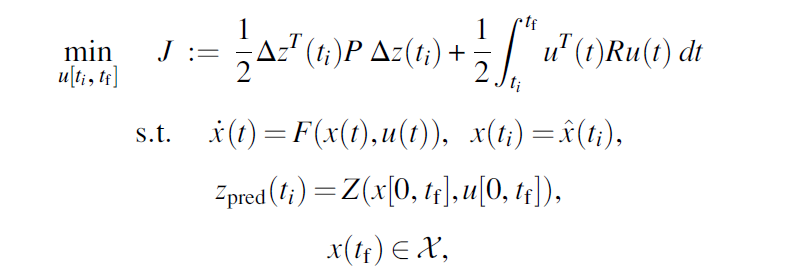

target = 10;

OCP = struct('Nx', Nx, 'Nu', Nu, 'Ny',Ny, 'N', 5, ...
    'x_lu', [0*ones(Nx,1) inf*ones(Nx,1)],  ...
    'u_lu', [1*[0; 300; 273] [20; 400; 400]], ...
    'x_eq',[], ...
    'u_eq',[], ...
    'F',F, ...
    'L',@(u) 0.5*(u)'*diag([1E-16, 1E-16, 1E-16])*(u), ...
    'Lf',@(x,yd) 0.5*(g(x)-yd)'*diag([1])*(g(x)-yd) );

[xout, uout]  = singleShooting(OCP, x0, target);

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:       15
Number of nonzeros in Lagrangian Hessian.............:      120

Total number of variables............................:       15
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:       15
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:       15
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 5

[yopt,~,xopt] = simulateSystem(F, g, x0, uout');

## Plotting

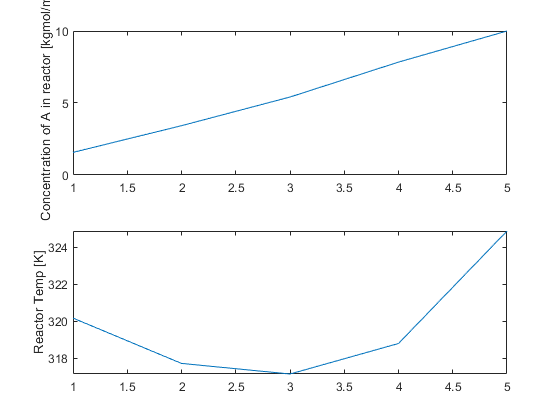

subplot(2,1,1)
plot(xopt(1,:)')
ylabel('Concentration of A in reactor [kgmol/m^3]')
subplot(2,1,2)
plot(xopt(2,:)')
ylabel('Reactor Temp [K]')

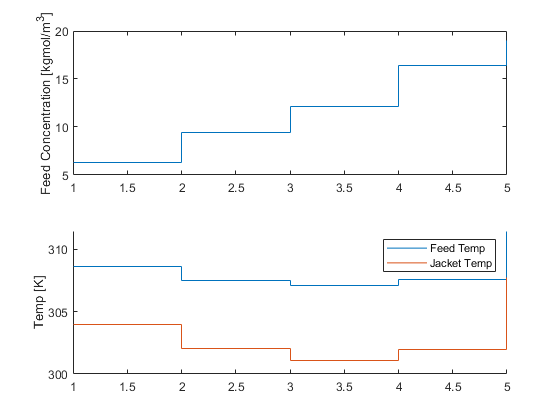


figure()
subplot(2,1,1)
stairs(uout(1,:)')
ylabel('Feed Concentration [kgmol/m^3]')
subplot(2,1,2)
hold on
stairs(uout(2,:)'); stairs(uout(3,:)')
legend('Feed Temp','Jacket Temp');
ylabel('Temp [K]');  hold off